net = googlenet;
inputSize = net.Layers(1).InputSize

inputSize =    224   224     3




classNames = net.Layers(end).ClassNames;
numClasses = numel(classNames);
disp(classNames(randperm(numClasses,10)));

    'Leonberg'
    'water ouzel'
    'book jacket'
    'microwave'
    'ice cream'
    'beagle'
    'yurt'
    'shoji'
    'goblet'
    'beach wagon'



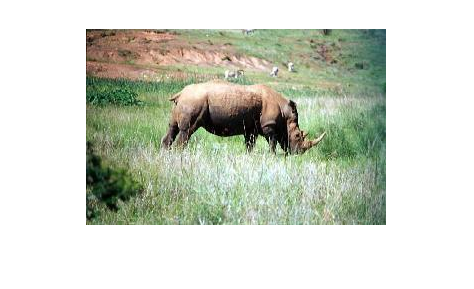

I = imread('image_0051.jpg');
figure
imshow(I)

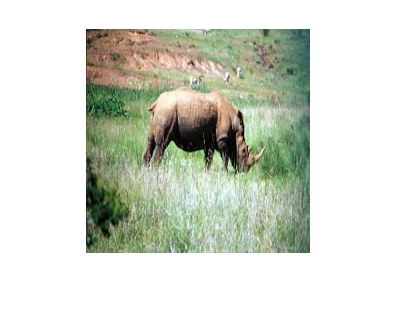


I = imresize(I,inputSize(1:2));
figure
imshow(I)



[label,scores] = classify(net,I);
label

label = categorical
     hog 


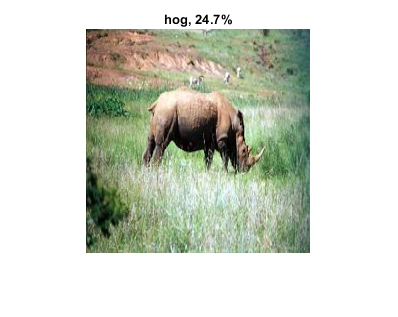



figure
imshow(I)
title(string(label) + ", " + num2str(100*scores(classNames == label),3) + "%");

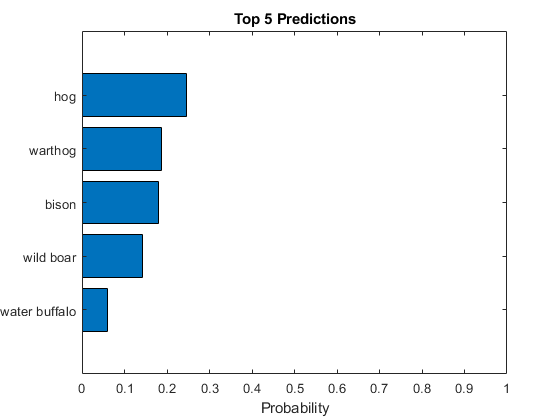




[~,idx] = sort(scores,'descend');
idx = idx(5:-1:1);
classNamesTop = net.Layers(end).ClassNames(idx);
scoresTop = scores(idx);

figure
barh(scoresTop)
xlim([0 1])
title('Top 5 Predictions')
xlabel('Probability')
yticklabels(classNamesTop)